This file produces the SIR full 3D figure in the paper. Given an initial condition, or a number of initial conditions it plots the trajectory under the SIR dynamics described in the paper

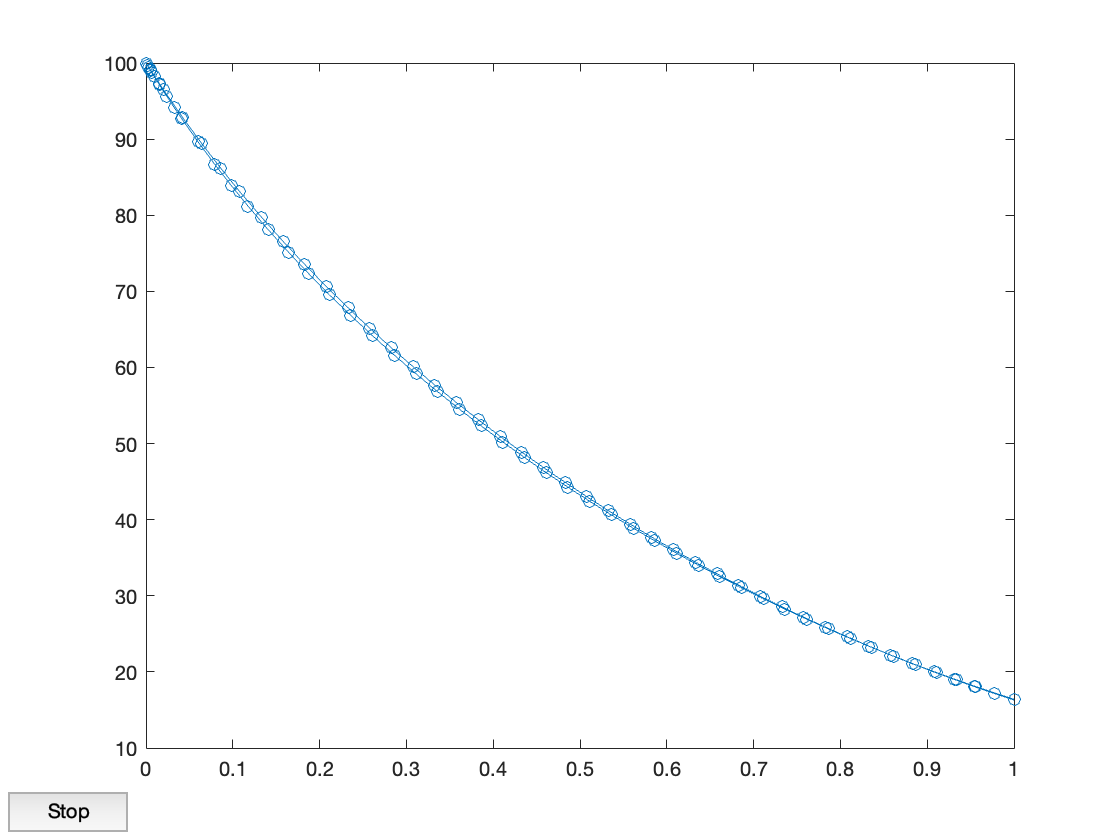

opts = odeset('Events', @impact, 'OutputFcn',@odeplot ,'OutputSel', 3);
for i = 1:2
    x_now = [i*5 100 - 5*i 100];
    [t, y] = ode45(@eom, [0, T], x_now, opts);           
            % apply the reset map
    IC = y(end, :);
    t = t(end);
    hold on
            
    while t < T
        IC = reset(IC)
        [t, y] = ode45(@eom, [t, T], IC, opts);
        IC = y(end, :);            
        t = t(end); 
        hold on;
    end   
end

function dydx = eom(t, y)
    b = 10; g = 1; d = 2; mu = 1;
    dydx = zeros(size(y));
     dydx(1) =  - b*y(1)*y(2)/y(3) + ...
       mu*(y(2) + y(3));
     dydx(2) = b*y(1)*y(2)/y(3) - ...
       (g + mu + d) * y(2);
     dydx(3) = -d*y(2);

end

function [position,isterminal,direction] = impact(t, y)
     a = 0.3;
     position = y(2) - a*y(3);
     position = y(1);
     isterminal = 1;
     direction = 0;
end

function y_plus = reset(y)
     f = 0.3;
     y_plus(1) = y(1);
     y_plus(2) = (1 - f)*y(2);
     y_plus(3) = y(3);
end